# Cross-validation

Cross-validation is performed by removing one radar at the time and estimating bird density at the exact same location (and time). Comparing the estimation (and uncertainty estimated) to the true value allows to assess the model. 

## 1. Loading

clear all; load('../1-Cleaning/data/dc_corr.mat'); load('../2-Inference/data/Density_inference.mat'); load coastlines; addpath('functions\')
dclat = [dc.lat]'; dclon = [dc.lon]'; dcname={dc.name};
clear dc

## 2. Model

### 2.1 Multi-night scale

Compute the full covariance matrix

Dtime=squareform(pdist(multi.T(~multi.isnan)));
Ddist=squareform(pdist([dclat(multi.R(~multi.isnan)) dclon(multi.R(~multi.isnan))],@lldistkm));

Caa = multi.cov.C(Ddist,Dtime);

[~,tmp] = meshgrid(multi.t,1:numel(multi.r));
cvmulti.i_r=tmp(~multi.isnan);

cvmulti.Mn_est=nan(size(multi.Mn));
cvmulti.Mn_sig=nan(size(multi.Mn));

For each radar, ignore all its data

for i_d=1:numel(multi.r)

    neigh=cvmulti.i_r~=i_d;
    sim=find(~neigh);
    
    % Remove also radars within 100km
    %sim(Dist_km_sf(i,:)<100)=false;
    
    lambda = Caa(neigh,neigh)  \  Caa(neigh,sim);
    cvmulti.Mn_est(sim) =  lambda' * multi.Mn(neigh);
    cvmulti.Mn_sig(sim) = sqrt(sum(multi.cov.parm(1:3)) - diag(lambda' * Caa(neigh,sim)));
end

Add the trend back

cvmulti.M_est=nan(size(multi.M)); cvmulti.M_sig=nan(size(multi.M));
cvmulti.M_est(~multi.isnan) = cvmulti.Mn_est+dclat(multi.R(~multi.isnan))*multi.w(2)+multi.w(1);
cvmulti.M_sig(~multi.isnan) = cvmulti.Mn_sig;

### 2.2 Intra-night scale

Build the covariance function from the distance

Ddist_sm = squareform(pdist([dclat dclon], @lldistkm));

D=table();
for i_t=1:numel(multi.t)
    id = find(data.day==i_t);
    d = table();
    d.Ddist = intrahape(Ddist_sm(data.radar(id),data.radar(id)),[],1);
    d.Dtime = intrahape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    D=[D ; d];
end

C_intra = sparse(D.Did1,D.Did2, intra.cov.C(D.Ddist, D.Dtime));

Estimate the value removing all values of the radar.

cvintra.In_est=nan(size(intra.In));
cvintra.In_sig=nan(size(intra.In));

for i_t=1:numel(multi.t)
    id_t=find(i_t==data.day);
    for i_r=1:numel(multi.r)
        
        id_r = i_r==data.radar(id_t);
    
        Lambda = C_intra(id_t(~id_r),id_t(~id_r))\C_intra(id_t(~id_r),id_t(id_r));
        
        cvintra.In_est(id_t(id_r)) = Lambda' * intra.In(id_t(~id_r));
        cvintra.In_sig(id_t(id_r)) = sqrt(sum(intra.cov.parm(1:3)) - sum(Lambda.*C_intra(id_t(~id_r),id_t(id_r))));

    end
end

Add the curve trend and variance normalization back

cvintra.I_est = cvintra.In_est .* sqrt(bsxfun(@power,data.NNT,0:intra.bpo)*intra.b) + bsxfun(@power,data.NNT,0:intra.apo)*intra.a;
cvintra.I_sig = sqrt(cvintra.In_sig.^2 .* (bsxfun(@power,data.NNT,0:intra.bpo)*intra.b));

### 2.3 Reassemble

cv.denst_est = cvmulti.M_est(data.dayradar) + cvintra.I_est;
cv.denst_sig = sqrt(cvmulti.M_sig(data.dayradar).^2 + cvintra.I_sig.^2);

Transform back to the original space. Value below zero cannot be converted. 

if any(cv.denst_est<0)
    disp(['WARNING: Remove ' num2str(sum(cv.denst_est<0)) ' value(s) because <0'])
    cv.denst_est(cv.denst_est<0)=nan;
end
cv.dens_est = (cv.denst_est).^(1/pow);

Visual figure

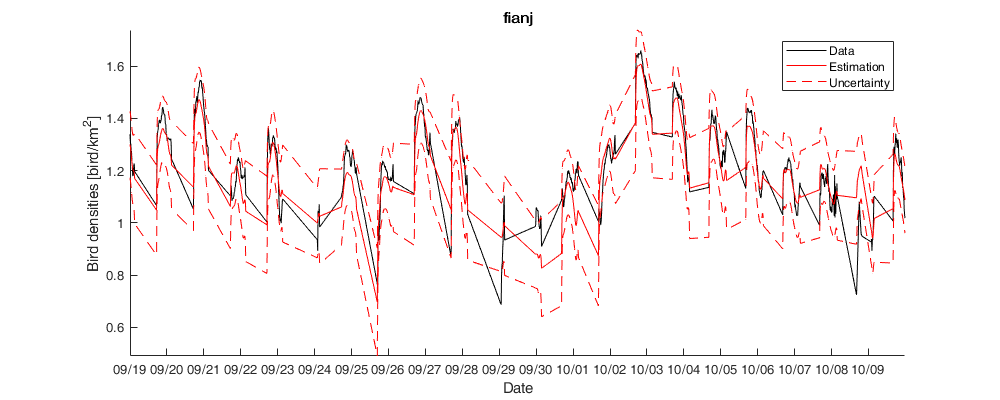

i_d=22;
figure('position',[0 0 1000 400]); hold on;
id=data.radar==i_d;
plot(data.time(id),data.denst(id),'k');
plot(data.time(id),cv.denst_est(id),'r')
plot(data.time(id),cv.denst_est(id)-cv.denst_sig(id),'--r')
plot(data.time(id),cv.denst_est(id)+cv.denst_sig(id),'--r');
datetick('x');axis tight; xlabel('Date'); ylabel('Bird densities [bird/km^2]'); legend('Data','Estimation','Uncertainty'); title(dcname(i_d))

### 2.4 Assessment of the model

Root-mean-squared error

cv.rmse_denst = sqrt(nanmean( (cv.denst_est-data.denst ).^2 ));
cv.rmse_dens = sqrt(nanmean( (cv.dens_est-data.dens ).^2 ));
disp(['RMSE: ' num2str(cv.rmse_dens) ' (bird/km^2)'])

RMSE: 17.6655 (bird/km^2)


The normalized error of estimation measures the misfit of the estimation divided by the standard deviation of estimation. 


$$\frac{{B^p }^* -{B^p }^{\textrm{true}} }{\sigma_{{B^p }^* } }$$


cv.nee = (data.denst-cv.denst_est)./cv.denst_sig;

Histogram of normalized error of estimation. Ideally, the histogram should be a standard Gaussian (zero-mean variance of one)

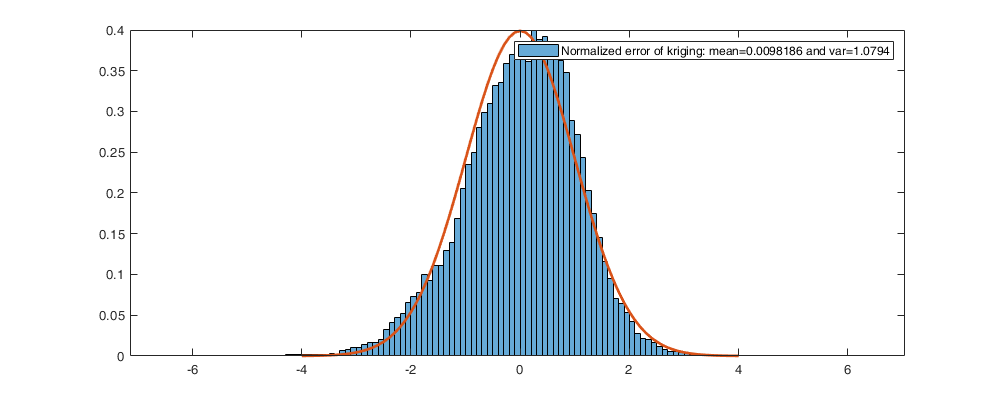

figure('position',[0 0 1000 400]); histogram( cv.nee ,'Normalization','pdf');
hold on; plot(-4:.1:4,normpdf(-4:.1:4),'linewidth',2)
legend(['Normalized error of kriging: mean=' num2str(nanmean(cv.nee)) ' and var=' num2str(nanvar(cv.nee))]);

QQ-plot

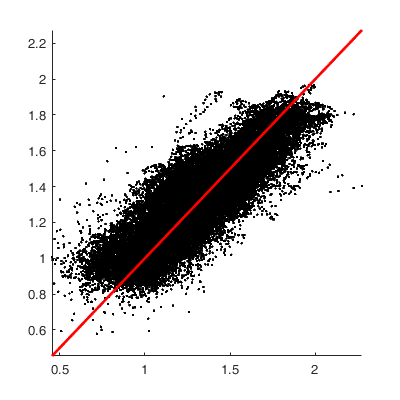

figure('position',[0 0 400 400]); hold on
plot(data.denst,cv.denst_est,'.k'); 
% coef=data.dens(~isnan(cv.dens_est)) \ cv.dens_est(~isnan(cv.dens_est));
plot([min(data.denst) max(data.denst)],[min(data.denst) max(data.denst)],'-r','LineWidth',2);
axis([min(data.denst) max(data.denst) min(data.denst) max(data.denst)])

Normalized error per radar

cv_nee_avg=splitapply(@mean,cv.nee,data.radar);
cv_nee_std=splitapply(@std,cv.nee,data.radar);

Illustration

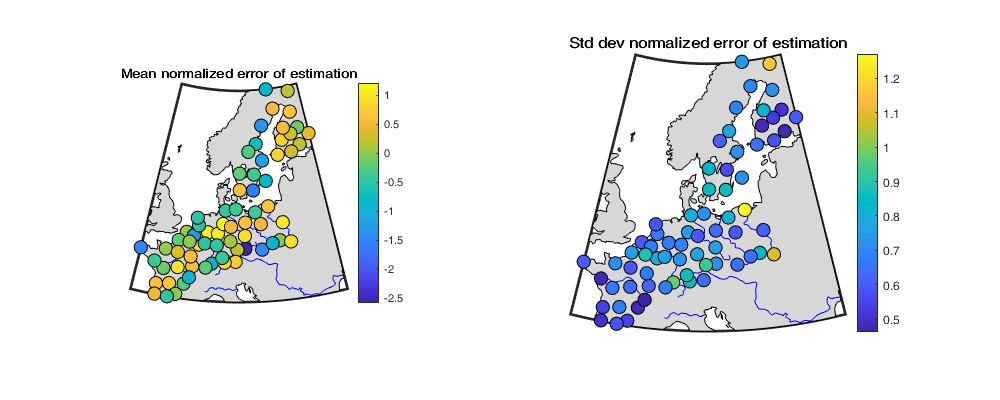

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,cv_nee_avg,'filled','MarkerEdgeColor','k'); title('Mean normalized error of estimation'); colorbar;
subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,cv_nee_std,'filled','MarkerEdgeColor','k'); title('Std dev normalized error of estimation'); colorbar;

## 3. Comparing to scatter interpolation

Define the ratio distance/time for the interpolation (eg. 1 day = 1degree lat/lon). This value as been optimized with the data (see Appendix below).

ratio_coord_time= 13;

### 3.1 Estimation

interpo.nn=nan(size(data.dens)); interpo.l=nan(size(data.dens)); interpo.n=nan(size(data.dens));
for i_d=1:numel(multi.r)
  sim = i_d==data.radar;
  
  Fnn = scatteredInterpolant(data.lat(~sim),data.lon(~sim),data.time(~sim).*ratio_coord_time,data.dens(~sim),'nearest');
  Fl = scatteredInterpolant(data.lat(~sim),data.lon(~sim),data.time(~sim).*ratio_coord_time,data.dens(~sim),'linear');
  Fn = scatteredInterpolant(data.lat(~sim),data.lon(~sim),data.time(~sim).*ratio_coord_time,data.dens(~sim),'natural');
  
  interpo.nn(sim) = Fnn(data.lat(sim),data.lon(sim),data.time(sim).*ratio_coord_time);
  interpo.l(sim) = Fl(data.lat(sim),data.lon(sim),data.time(sim).*ratio_coord_time);
  interpo.n(sim) = Fn(data.lat(sim),data.lon(sim),data.time(sim).*ratio_coord_time);

end

Figure

Visual figure

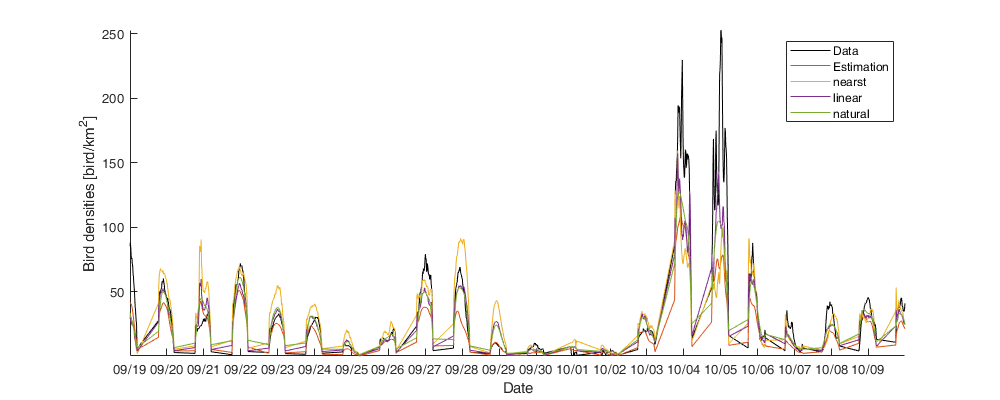

i_d=49;
figure('position',[0 0 1000 400]); hold on;
id=data.radar==i_d;
plot(data.time(id),data.dens(id),'k');
plot(data.time(id),cv.dens_est(id))
plot(data.time(id),interpo.nn(id));
plot(data.time(id),interpo.l(id));
plot(data.time(id),interpo.n(id));
datetick('x');axis tight; xlabel('Date'); ylabel('Bird densities [bird/km^2]'); legend('Data','Estimation','nearst','linear','natural');

### 3.2 Assessement

Histogram of estimation error with RMSE and abs error in legend

cv.rmse_nn =sqrt(nanmean((interpo.nn - data.dens).^2));
cv.rmse_l =sqrt(nanmean((interpo.l - data.dens).^2));
cv.rmse_n =sqrt(nanmean((interpo.n - data.dens).^2));
cv.r2_dens = 1-sum((cv.dens_est-data.dens ).^2)/sum((data.dens-mean(data.dens) ).^2);
cv.r2_nn = 1-sum((interpo.nn-data.dens).^2)/sum((data.dens-mean(data.dens) ).^2);
cv.r2_l = 1-sum((interpo.l-data.dens).^2)/sum((data.dens-mean(data.dens) ).^2);
cv.r2_n = 1-sum((interpo.n-data.dens).^2)/sum((data.dens-mean(data.dens) ).^2);

Display

cv

cv = struct with fields:
     denst_est: [50436×1 double]
     denst_sig: [50436×1 double]
      dens_est: [50436×1 double]
    rmse_denst: 0.1403
     rmse_dens: 17.6655
           nee: [50436×1 double]
       rmse_nn: 23.1713
        rmse_l: 18.4955
        rmse_n: 17.9504
       r2_dens: 0.5855
         r2_nn: 0.2869
          r2_l: 0.5456
          r2_n: 0.5720


Histogram

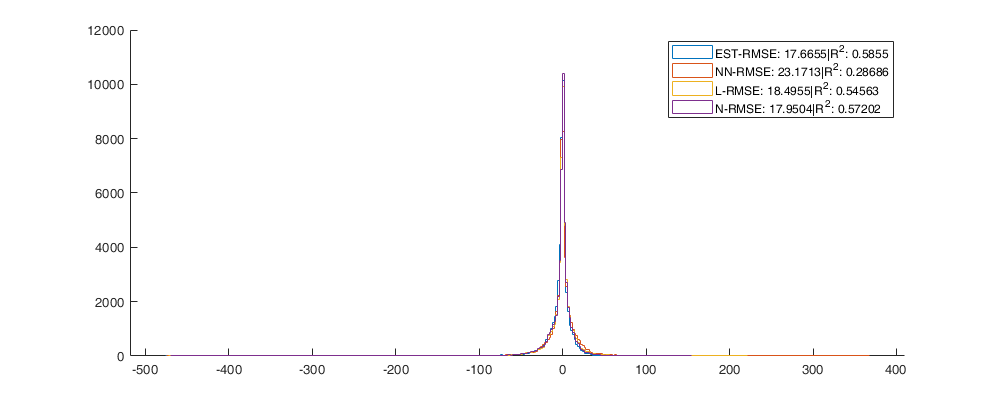

figure('position',[0 0 1000 400]); hold on;
histogram(cv.dens_est - data.dens,'DisplayStyle', 'stairs','DisplayName',['EST-RMSE: ' num2str(cv.rmse_dens) '|R^2: ' num2str(cv.r2_dens)]);
histogram(interpo.nn - data.dens,'DisplayStyle', 'stairs','DisplayName',['NN-RMSE: ' num2str(cv.rmse_nn) '|R^2: ' num2str(cv.r2_nn)]);
histogram(interpo.l - data.dens,'DisplayStyle', 'stairs','DisplayName',['L-RMSE: ' num2str(cv.rmse_l) '|R^2: ' num2str(cv.r2_l)]);
histogram(interpo.n - data.dens,'DisplayStyle', 'stairs','DisplayName',['N-RMSE: ' num2str(cv.rmse_n) '|R^2: ' num2str(cv.r2_n)]);
legend

Histogram of transoformed estimation error with RMSE and abs error in legend

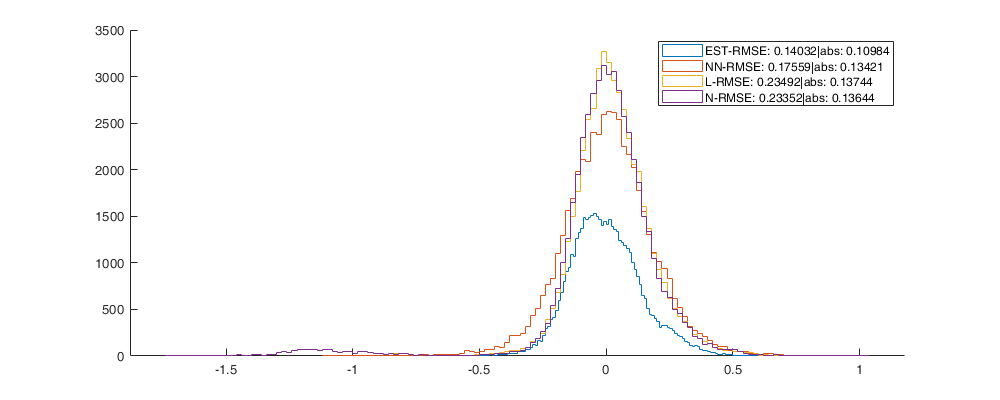

figure('position',[0 0 1000 400]); hold on;
histogram(cv.denst_est - data.denst,'DisplayStyle', 'stairs','DisplayName',['EST-RMSE: ' num2str(sqrt(nanmean((cv.denst_est - data.denst).^2))) '|abs: ' num2str(nanmean(abs(cv.denst_est - data.denst)))]);
histogram(max(interpo.nn,0).^pow - data.denst,'DisplayStyle', 'stairs','DisplayName',['NN-RMSE: ' num2str(sqrt(nanmean((max(interpo.nn,0).^pow - data.denst).^2))) '|abs: ' num2str(nanmean(abs(max(interpo.nn,0).^pow - data.denst)))]);
histogram(max(interpo.l,0).^pow - data.denst,'DisplayStyle', 'stairs','DisplayName',['L-RMSE: ' num2str(sqrt(nanmean((max(interpo.l,0).^pow - data.denst).^2))) '|abs: ' num2str(nanmean(abs(max(interpo.l,0).^pow - data.denst)))]);
histogram(max(interpo.n,0).^pow - data.denst,'DisplayStyle', 'stairs','DisplayName',['N-RMSE: ' num2str(sqrt(nanmean((max(interpo.n,0).^pow - data.denst).^2))) '|abs: ' num2str(nanmean(abs(max(interpo.n,0).^pow - data.denst)))]);
legend

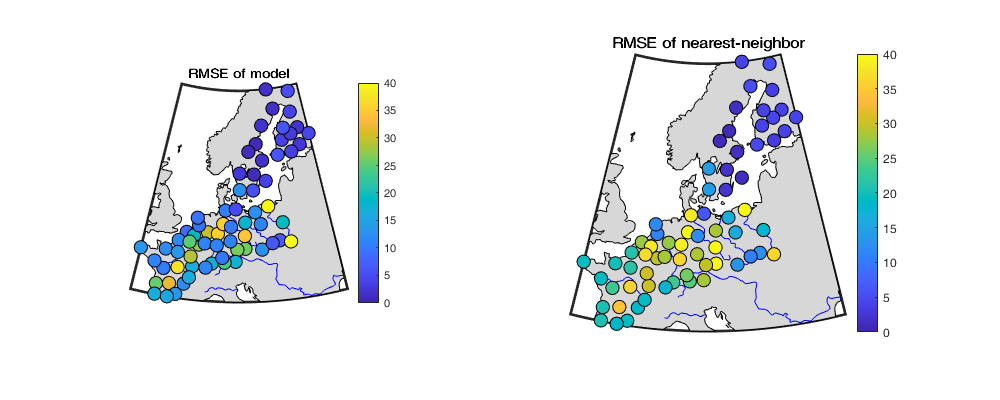

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,sqrt(splitapply(@nanmean,(cv.dens_est - data.dens).^2,data.radar)),'filled','MarkerEdgeColor','k');
caxis([0 40]); title('RMSE of model'); colorbar;
subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,sqrt(splitapply(@nanmean,(interpo.nn - data.dens).^2,data.radar)),'filled','MarkerEdgeColor','k'); 
caxis([0 40]); title('RMSE of nearest-neighbor'); colorbar;

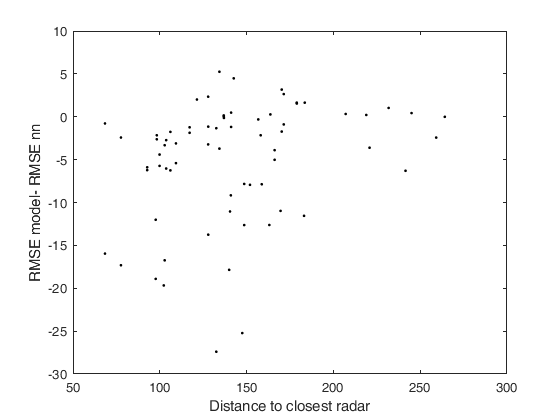

Ddist_sm(Ddist_sm==0)=Inf;
plot(min(Ddist_sm)',sqrt(splitapply(@nanmean,(cv.dens_est - data.dens).^2,data.radar))-sqrt(splitapply(@nanmean,(interpo.nn - data.dens).^2,data.radar)),'.k');
xlabel('Distance to closest radar'); ylabel('RMSE model- RMSE nn')

## 7. Save

save('data/Density_crossValidation.mat','cv','cvmulti','cvintra','interpo')

## Appendix: Calibrate` ratio_coord_time`

ratio_coord_time =    1000 *[ 0.0184    0.1006   -0.0024   -0.0007   -0.0013    0.0154    0.5188    0.0236    0.3456    0.0125    0.1205    0.1871    0.0738    0.1084    0.0266    0.0090    0.0036    0.6481   -0.0017    0.0131    0.3464 0.0130    0.9928    0.0130    0.0899    0.0130    0.0130    0.2673    0.0181    0.0202    2.4713    0.0571    0.5818    0.5503    0.0130    0.1414    0.0839    0.0040    0.1486    0.0179    0.0130    0.0130 0.4111    0.0040    0.0130    0.0130    0.1771   -0.0013    0.1080    0.0108    0.0235    0.0130    0.0074    0.0148    0.0332   -0.0013    0.0130   -0.0013    0.0091    0.0039   -0.0013    0.0388    0.0130 -0.0013    0.0104    0.0052    0.0039   -0.0013    0.0123];

parfor i_d=1:numel(dc)
  id1=find(D(i_d,:)>distlelim);
  id2=ismember(data.i_d,id1);
  id3=data.i_d==i_d;
  
  interpolafx =@(x) griddata(data.lat(id2),data.lon(id2),data.time(id2).*x,data.dens(id2),data.lat(id3),data.lon(id3),data.time(id3).*x,'natural');
  rmse = @(x) nansum( (interpolafx(x)-data.dens(id3)).^2 );
  
  % options = optimset('PlotFcns',{@optimplotfval,@optimplotx},'MaxFunEvals',100);
  options = optimset('MaxFunEvals',30);
  ratio_coord_time(i_d) = fminsearch(rmse,ratio_coord_time(i_d),options)
  % ratio_coord_time = fminbnd(rmse,0,1,options);
end

Figure

figure; histogram(ratio_coord_time(ratio_coord_time>0 & ratio_coord_time<100),100); xlabel('ratio_coord_time');
